## **SIO 207A HW-1**

**Ruipu Ji**

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultTextFontSize', 12);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');

Consider a discrete-time signal sampled from an analog signal $x\left(t\right)=\cos \left(2\pi \cdot t\right)+5\sin \left(6\pi \cdot t\right)$ with a sampling rate of 25 Hz. The amplitude (linear), magnitude (linear and logarithmic) and phase (linear) plots are generated by the following MATLAB code.

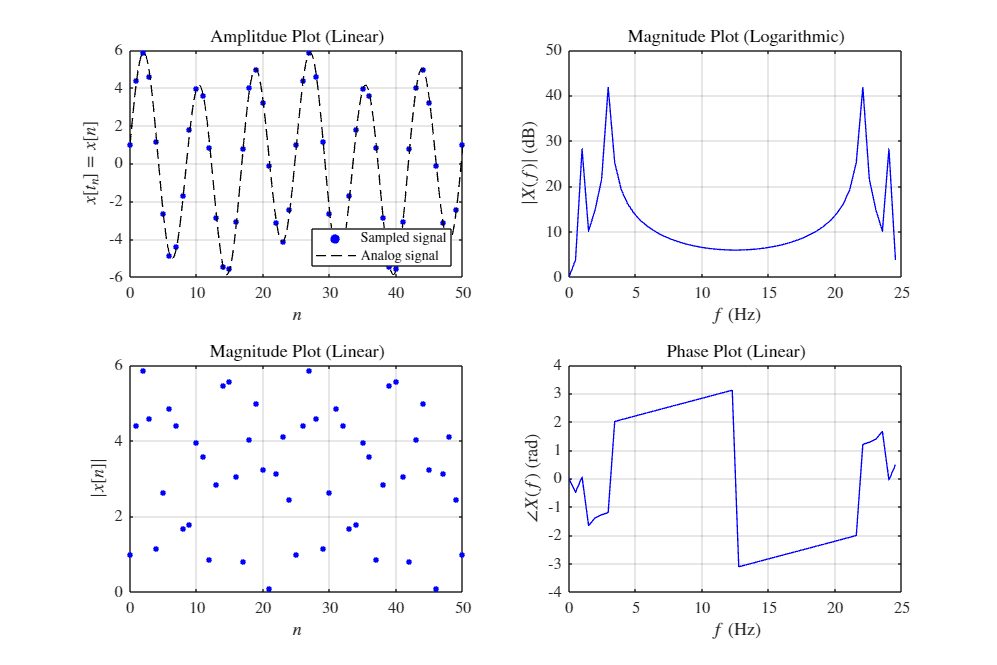

% Create a fine time vector for analog signal plotting and calculate sampled data points for discrete-time signal.
AnalogTimeVector = 0:(1/1000):2;
% Define the analog signal.
AnalogSignal = cos(2*pi*AnalogTimeVector) + 5*sin(6*pi*AnalogTimeVector);

% Create the sampled time vector and calculate the sampled discrete-time signal.
fs = 25; % fs = Sampling rate in Hz.
n = 0:1:50; % n = Sample number.
SampledTimeVector = n/fs;
SampledSignal = cos(2*pi*SampledTimeVector) + 5*sin(6*pi*SampledTimeVector);

% Calculate frequency characteristics of the discrete-time signal.
SampledSignal_fft = fft(SampledSignal); % Fourier transform of the discrete-time signal.
SampledSignal_magnitude = abs(SampledSignal_fft); % Magnitude of Fourier coefficients.
SampledSignal_magnitude_db = 20 * log10(SampledSignal_magnitude); % Logarithmic magnitude in dB.
SampledSignal_phase = angle(SampledSignal_fft); % Phase of Fourier coefficients.
FrequencyVector = (0:1/length(n):1-1/length(n)) * fs;  % Frequency axis in Hz

% Plot the result.
figure('Position',[0 0 1200 800]);

subplot(2,2,1); % Amplitude (linear) plot.
hold on;
scatter(n, SampledSignal,10, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b', 'LineWidth', 1);
plot(AnalogTimeVector*fs, AnalogSignal, 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([-6 6]);
yticks(-6:2:6);
xlabel('$n$');
ylabel('$x[t_n]=x[n]$');
legend('Sampled signal', 'Analog signal', 'Location', 'southeast');
title('Amplitdue Plot (Linear)');

subplot(2,2,3); % Magnitude (linear) plot.
hold on;
scatter(n, abs(SampledSignal), 10, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 50]);
xticks(0:10:50);
ylim([0 6]);
yticks(0:2:6);
xlabel('$n$');
ylabel('$|x[n]|$');
title('Magnitude Plot (Linear)');

subplot(2,2,2); % Magnitude (logarithmic) plot.
hold on;
plot(FrequencyVector, SampledSignal_magnitude_db, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 25]);
xticks(0:5:25);
ylim([0 50]);
yticks(0:10:50);
xlabel('$f$ (Hz)');
ylabel('$|X(f)|$ (dB)');
title('Magnitude Plot (Logarithmic)');

subplot(2,2,4); % Phase (linear) plot.
hold on;
plot(FrequencyVector, SampledSignal_phase, 'b', 'LineWidth', 1);
grid on;
box on;
xlim([0 25]);
xticks(0:5:25);
ylim([-4 4]);
yticks(-4:1:4);
xlabel('$f$ (Hz)');
ylabel('$\angle X(f)$ (rad)');
title('Phase Plot (Linear)');

Figure 1. The amplitude (linear), magnitude (linear and logarithmic) and phase (linear) plots for a discrete-time signal sampled from an analog signal $x\left(t\right)=\cos \left(2\pi \cdot t\right)+5\sin \left(6\pi \cdot t\right)$ with a sampling rate of 25 Hz.